# Problem #3

## (1)

First we must go over the concepts behind the drag coefficient.

the drag coefficient, $C_d$ is


$$C_D =C_{\mathrm{do}} +C_{\mathrm{di}} \;\;\;\;\;\;\cdots \left(1\right)$$


where

$C_{\mathrm{do}}$ is the sum of the skin friction and form, and this is inversly proportional to the $\mathrm{Re}$ $\equiv$ Reynold's Number, which is,


$$\mathrm{Re}=\rho \frac{\mathrm{VL}}{\mu }\;\;\;\;\cdots \left(2\right)$$


where $\rho$ is the density of the fluid, $V$is the velocity, $L$ is the length of the wing, and $\mu$ is the viscosity of the fluid.

And $C_{\mathrm{di}}$ is the induced drag which is derived as 


$$C_{\mathrm{di}} \;=\frac{C_l^2 }{\pi \left(\mathrm{AR}\right)e}\;\;\;\;\cdots \left(3\right)$$


$C_l \;$is the lift coefficient,

$\mathrm{AR}\equiv \;\mathrm{Aspect}\;\mathrm{Ratio}=\frac{b^2 }{S}=\frac{{\left(\mathrm{wing}\;\mathrm{span}\right)}^2 }{\left(\mathrm{wing}\;\mathrm{area}\right)}$, and $e$ is the efficiency factor.

From (1), (2), and (3) we can see that there is a relation between the Reynolds Number and the drag coefficient, 

and to verify that it is appropriate to extrapolate the velocity by drag force data given we will manipulate the given data and attempt to elucidate the relationship between the two values.

This will provide dynamic similarity in that the object and flow velocity combination with the same Reynold's Number exhibit the same flow characteristics.

% First we set up the given data of the velocity 
% and the drag Forces
V_inf = [14.9, 18.1, 21.6, 25.2, 29.3, 32, 34.2, 36.9, 39]; % [m/s]
drag_F = [0.31, 0.44, 0.61, 0.8, 1.08, 1.3, 1.46, 1.7, 1.9]; % [N] 

% And set-up other constants given at the condition of sea-level
dens = 1.2250; % [kg/m^3]
% At the sea-level temperature which is 288.16 K = 15.01 C, the viscosity is 
visco = 17.89 * 10^(-6); % [N*s/m^2]
% The wing span and the average chord of the wing are also given (at the scale of 1:10)
span = 1.5; % [m]
avg_chord = 0.08; % [m]
% From the wing span and the average chord the area is
area = span * avg_chord; % [m^2]

Subsequently, using the drag force formula


$$D\;=\frac{1}{2}\rho V_{\infty }^2 C_D S$$


where $\rho$ is density, $V_{\infty }$ is the velocity, $C_D$ is the drag coefficient, and $S$ is the area of the wing.

We will solve this formula for $C_D$


$$C_D$$
 
$$=\frac{2D}{\rho V_{\infty }^2 S}$$


% The drag coefficient (vector) becomes
drag_coeff = 2 * drag_F / dens ./ V_inf / area;

Also using 


$$\textrm{Re}=\rho \frac{\textrm{VL}}{\mu }$$


% The Reynold's number (vector) becomes
reynold = dens * V_inf * span / visco; 

Now we plot the drag coefficient (y-axis) by the Reynold's Number (x-axis) to find their relation

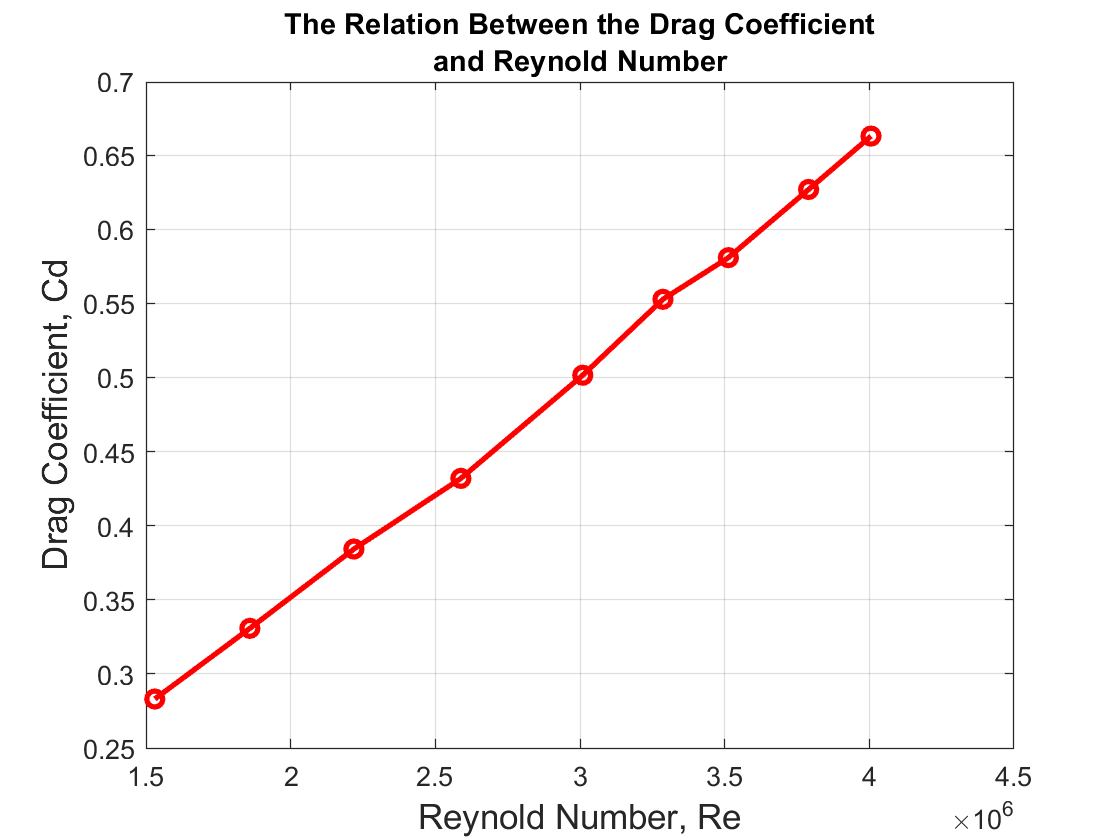

% Adjusting the fontsize and linewidth
fontsize = 13;
linewidth = 2;

% Plotting 
figure(1)
plot(reynold, drag_coeff, 'Color','r','LineStyle','-','Marker','o','LineWidth',linewidth)
title({'The Relation Between the Drag Coefficient', 'and Reynold Number'})
xlabel('Reynold Number, Re','fontsize', fontsize)
ylabel('Drag Coefficient, Cd', "FontSize",fontsize)
box on
grid on

From this, we can say that the drag coefficient and the Reynold's Number has a linearly proportional relationship which approves of the dynamic similarity of the given data.

In conclusion, we are able to extrapolate the data in order to obtain the drag force for the velocity of 160 km/hr.

## (2)

To extrapolate the drag force for velocity of the given data set we will use the method of linear regression

% Use polyfit to fit the data to the predicted linear regression
p = polyfit(V_inf, drag_F, 1);
% Call polyval to call the predicted drag force values for the
% obtained linear regression
drag_F_fit = polyval(p, V_inf);
% The SSE value (Sum of Squared Errors) is
sse = sum((drag_F - drag_F_fit).^2);
% The SST value (Sum of Squared Total) is
sst = sum((drag_F - mean(drag_F)).^2);
% Thus the coefficient of determination, Rsq is
Rsq = 1 - sse/sst;

The variance of the predicted linear regression is 

display(Rsq);

Rsq = 0.9843

Which is very good. Hence we can use this reliable linear regression

to obtain the drag force at velocity 160 km/hr.

% The linear regression has 
% A slope of 
p(1);
% A y-intercept of 
p(2);

% Convert 160 km/hr to m/s
V_find = 160 * 1000 / 3600; % [m/s]

% Finally the drag force is 
drag_F160 = p(1) * V_find + p(2);

Additionally, the graph with the point of (v, D) = (V_find, drag_F160) (*which is the point for when the velocity is 160 km/hr) will be plotted for clarification

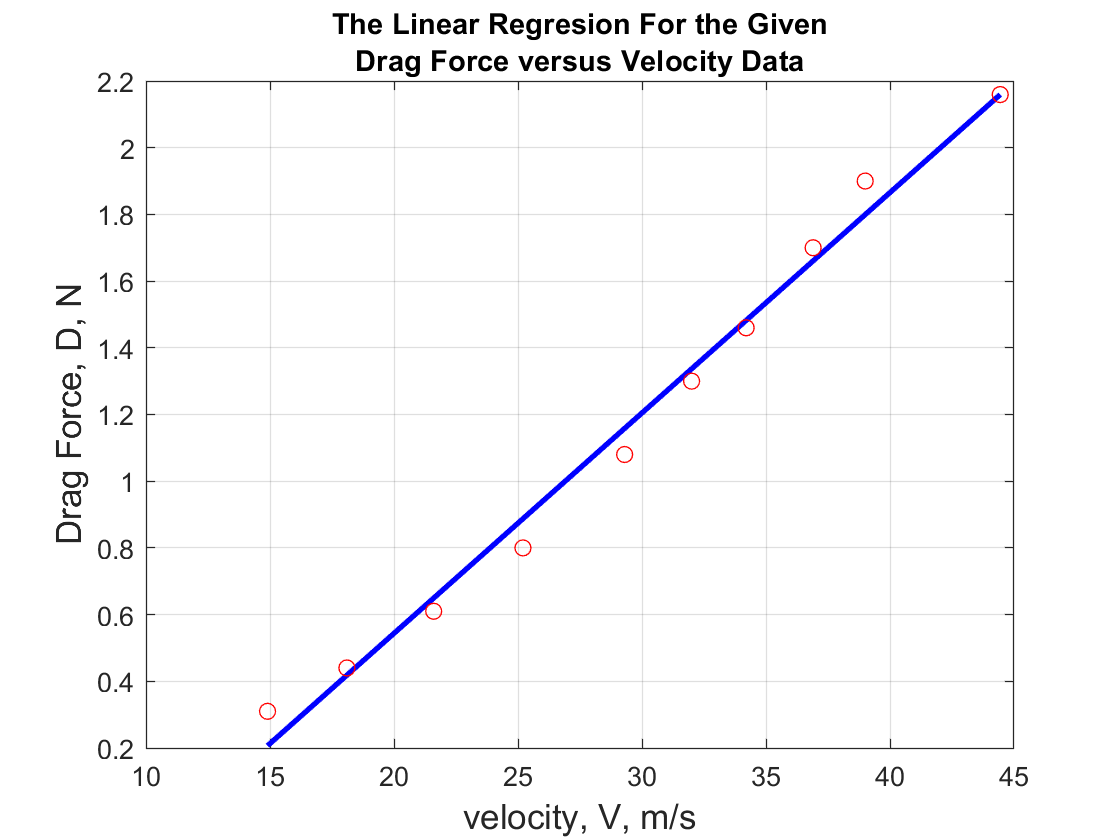

% Concatenate the data point for the velocity of 160 km/hr and the corresponding drag force 
V_inf = [V_inf V_find];
drag_F = [drag_F drag_F160];
drag_F_fit = [drag_F_fit drag_F160];

% Plotting 
figure(2)
plot(V_inf, drag_F_fit, 'color','b', 'LineStyle','-','LineWidth',linewidth)
title({'The Linear Regresion For the Given','Drag Force versus Velocity Data'})
xlabel('velocity, V, m/s','FontSize',fontsize)
ylabel('Drag Force, D, N', 'FontSize',fontsize)
box on
grid on
hold on
plot(V_inf, drag_F, 'color', 'r', 'Marker','o', 'LineStyle','none')
hold off

ANS:

fprintf('The drag force at 160 km/hr is %f N.',drag_F160);

The drag force at 160 km/hr is 2.159273 N.